%wczytanie koniecznych parametrów i wyliczenie wzocnień oraz punktów równowagi 
clear all
close all
run("wyliczanie_jacobianow_oraz_p_row.mlx")

ans = 0.0100

mwag_cal = -18.2574

close all
initial_x = 0.0212;
initial_x = 0.013;
max_x = 0.0212;
expected_z = 0.01;
KW = -[polyval(p_z,expected_z) polyval(p_v,expected_z) polyval(p_i,expected_z)];
Kw = -[polyval(p_z,expected_z)*max_x polyval(p_v,expected_z) polyval(p_i,expected_z)*3];

obsInfo = rlNumericSpec([3 1], LowerLimit=[-1 -1 -1]', UpperLimit=[ 1 1 1]');
actInfo = rlNumericSpec([1 1],"UpperLimit",1,"LowerLimit",-1); 


obsInfo.Name = "observations";
obsInfo.Description = "position z,, velocity v, current";

actInfo.Name = "control";

env = rlSimulinkEnv("MODEL_neural","MODEL_neural/controller",obsInfo,actInfo);
env.ResetFcn = @start;

Ts = 5e-3;
Tf = 0.5;

#### CRITIC

% % Observation path
% obsPath = featureInputLayer(3, Name="obsInLyr");
% 
% % Action path
% actPath = featureInputLayer(1, Name="actInLyr");
% 
% % Common path
% commonPath = [
%     concatenationLayer(1,2,Name="concat")
%     fullyConnectedLayer(50)
%     tanhLayer()
%     fullyConnectedLayer(50)
%     tanhLayer()
%     fullyConnectedLayer(1,Name="QValue")
%     ];
% 
% % Create the network object and add the layers
% criticNet = dlnetwork();
% criticNet = addLayers(criticNet,obsPath);
% criticNet = addLayers(criticNet,actPath);
% criticNet = addLayers(criticNet,commonPath);


% % Connect the layers
% criticNet = connectLayers(criticNet, ...
%     "obsInLyr","concat/in1");
% criticNet = connectLayers(criticNet, ...
%     "actInLyr","concat/in2");


% critic = rlQValueFunction(criticNet, ...
%     obsInfo,actInfo, ...
%     ObservationInputNames="obsInLyr", ...
%     ActionInputNames="actInLyr");



% % Observation and action paths
% obsPath = featureInputLayer(3,Name="obsInLyr");
% actPath = featureInputLayer(1,Name="actInLyr");
% 
% % Common path
% commonPath = [
%     concatenationLayer(1,2,Name="concat")
%     quadraticLayer
%     fullyConnectedLayer(1,Name="value", ...
%         BiasLearnRateFactor=0,Bias=0)
%     ];
% %,Weights= [-1.1, -0.1, -1.1, -0.1, -0.1, -1.1 -0.1 -0.1 -0.1 -1.1]
% 
% criticNet = dlnetwork;
% criticNet = addLayers(criticNet,obsPath);
% criticNet = addLayers(criticNet,actPath);
% criticNet = addLayers(criticNet,commonPath);
% 
% criticNet = connectLayers(criticNet,"obsInLyr","concat/in1");
% criticNet = connectLayers(criticNet,"actInLyr","concat/in2");
% plot(criticNet)
observationPath = [
    featureInputLayer(3,Name="obsInLyr")
    concatenationLayer(1,2,Name="concat")
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(8)
    reluLayer
    fullyConnectedLayer(1,Name="QValueOutLyr")
    ];
actionPath = featureInputLayer(1,Name="actInLyr");


criticNet = dlnetwork;
criticNet = addLayers(criticNet, observationPath);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"actInLyr","concat/in2");

plot(criticNet)
criticNet = initialize(criticNet);
summary(criticNet)


   Initialized: true

   Number of learnables: 833

   Inputs:
      1   'obsInLyr'   3 features
      2   'actInLyr'   1 features



critic = rlQValueFunction(criticNet, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsInLyr", ...
    ActionInputNames="actInLyr", ...
    UseDevice='gpu');

getValue(critic,{rand(obsInfo.Dimension)},{rand(actInfo.Dimension)})


ans =

  gpuArray single

  8.2836e-04



#### ACTOR

% actorNet = [
%     featureInputLayer(3,Name="observation")
% 
%     fullyConnectedLayer(68)
%     reluLayer
%     fullyConnectedLayer(34)
%     reluLayer
%     fullyConnectedLayer(16)
%     reluLayer
%     fullyConnectedLayer(1)
%     tanhLayer()
% 
%     ];

actorNet = [
    featureInputLayer(3,Name="observation")
    fullyConnectedLayer(1, Name="lqr", Weights=[5 5 -2], BiasInitializer="zeros")
    reluLayer()
    ];

%     
% actorNet(2).Weights=[Kw];
% actorNet(2).Bias= 0
rng(0,"twister");
actorNet = dlnetwork(actorNet);
summary(actorNet)


   Initialized: true

   Number of learnables: 4

   Inputs:
      1   'observation'   3 features



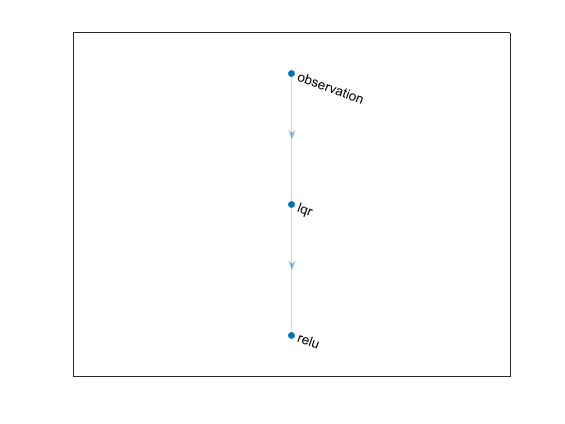

plot(actorNet)

actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo,UseDevice='gpu');

#### AGENT

agent = rlDDPGAgent(actor,critic);
agent.AgentOptions.SampleTime = Ts;
agent.AgentOptions.DiscountFactor = 0.99;
agent.AgentOptions.MiniBatchSize = 128;
agent.AgentOptions.ExperienceBufferLength = 5e3;

agent.AgentOptions.NumWarmStartSteps = 128;
agent.AgentOptions.NumStepsToLookAhead = 1;
agent.AgentOptions.PolicyUpdateFrequency  = 1;

actorOpts = rlOptimizerOptions( ...
    LearnRate=2.5e-4, ...
    GradientThreshold=100);

criticOpts = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=100);

agent.AgentOptions.ActorOptimizerOptions = actorOpts;
agent.AgentOptions.CriticOptimizerOptions = criticOpts;
% 
agent.AgentOptions.NoiseOptions.StandardDeviation = 0.04;
agent.AgentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-3;

% training options
trainOpts = rlTrainingOptions(...
    MaxEpisodes=4000, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    StopTrainingCriteria= "EpisodeReward" , ...
    StopTrainingValue = -9.9, ...
    SimulationStorageType="none");

    trainingOpts.UseParallel = true;
    trainingOpts.ParallelizationOptions.Mode = "sync";
    trainingOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;

% agent evaluator
 evl = rlEvaluator(EvaluationFrequency=25,NumEpisodes=5);
doTraining = 1;

if doTraining
    trainingStats = train(agent,env,trainOpts,Evaluator=evl);
    save("agent.mat","agent")
end

actorr = getActor(agent);
params = getLearnableParameters(actorr);
params

params = 2×1 cell array
    {[3.4193    3.6289    -3.6875]}
    {[-0.94439                   ]}




% figure 
%  subplot(3, 1, 1);
% plot(observationRL.time,observationRL.signals(1).values - observationRL.signals(1).values(1:254))
% grid on;
% hold on;
% % plot(observation.time,observation.signals(1).values)
% title("z obs difference")
% 
% 
% 
%  subplot(3, 1, 2);
% plot(observationRL.time,observationRL.signals(2).values - observationRL.signals(2).values(1:254) )
% grid on;
% hold on;
% % plot(observation.time,observation.signals(2).values)
% title("v obs difference")
% 
%   subplot(3, 1, 3);
% plot(observationRL.time,observationRL.signals(3).values - observationRL.signals(3).values(1:254))
% grid on;
% hold on;
% % plot(observation.time,observation.signals(3).values)
% title("i obs difference")